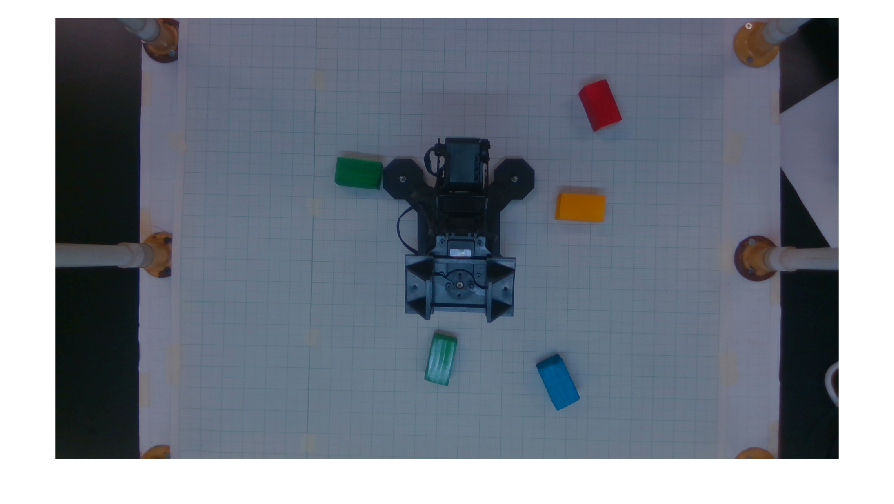


% Reading the image
img1 = imread("intro to rob\1_Color.png");
% filteredImage = imbilatfilt(img1, 1000, 50);
imshow(img1);

% imshowpair(img1, filteredImage, "montage")

% we dont use rgb since r cannot distingusih between blue and green, g is
% identical everywhere and b blends in its background.
weights = gradientweight(img1, "RolloffFactor", 3);
SE = strel("disk", 3);
weights = imopen(weights, SE);
weights = imcomplement(im2gray(weights));

Masking Red block

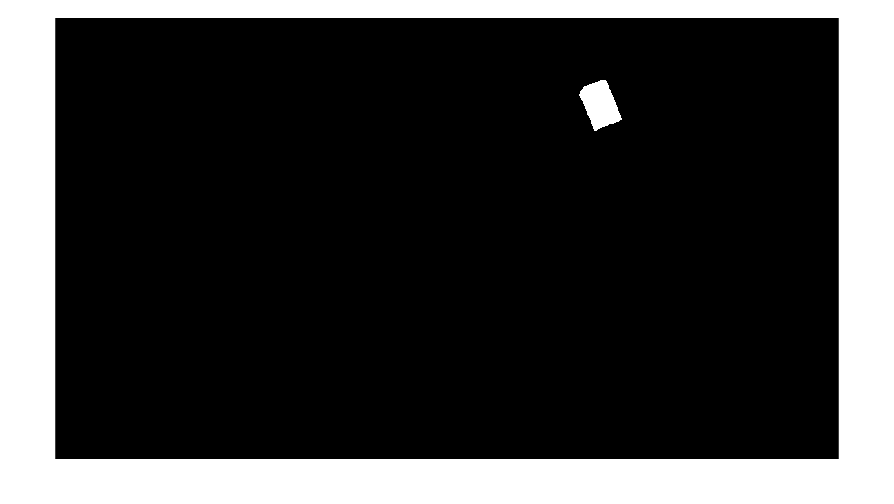

% Coverting rgb to LAB
img1lab = rgb2lab(img1);
[l a b] = imsplit(img1lab);

% Converting rgb to HSV
img1hsv = rgb2hsv(img1);
[h s v] = imsplit(img1hsv);

% h extracts red color, and s extracts the color red where the saturation
% is high
redmask = h > 0.9 & s > 0.5 ;
% redmask = activecontour(img1, redmask, 10, "Chan-Vese", "SmoothFactor", 0.3, "ContractionBias", -0.4);
% imshow(redmask);
redmask = imfill(redmask, "holes");
redmask = bwareaopen(redmask, 200); % size of actual box around 8200
SE = strel("disk", 3);
redmask = imclose(redmask, SE);
% redmask = imsegfmm(weights, redmask, 0.1);
imshow(redmask);

Masking Yellow block

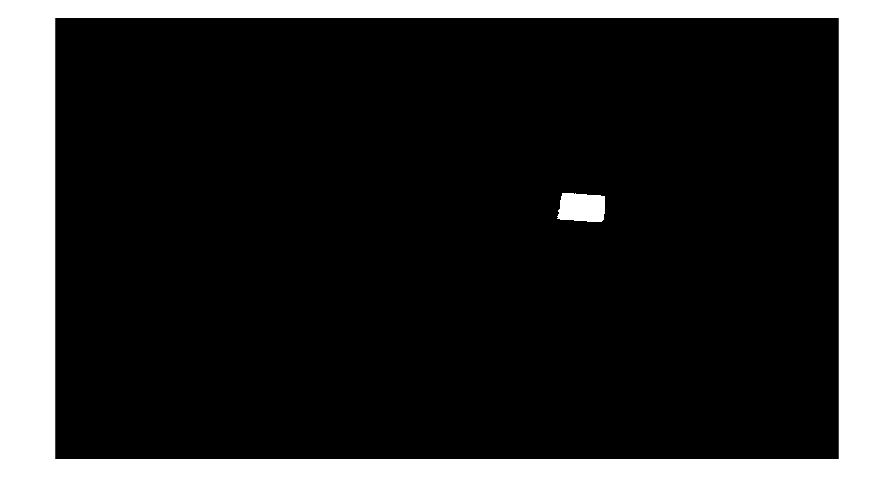

% h extracts color, s extracts regions of yellow with ihgh saturation and v
% ignores the dark yellow areas of the camera stand
yellowmask = s > 0.5 & h < 0.105 & v > 0.45;
yellowmask = imfill(yellowmask, "holes");
yellowmask = bwareaopen(yellowmask, 200);
imshow(yellowmask);

Masking Green Block

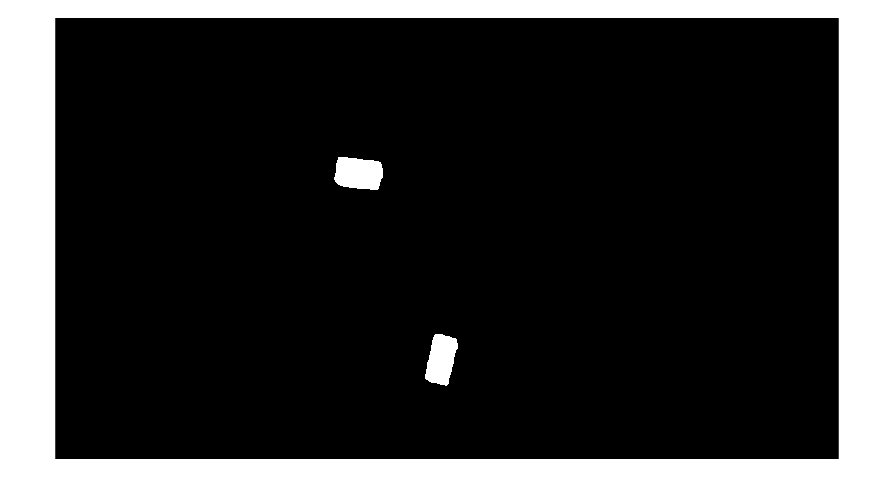

% the a channel distinguished green from others distinctively
greenmask = a < -10;
greenmask = imfill(greenmask, "holes");
greenmask = bwareaopen(greenmask, 200);
SE = strel("disk", 3);
greenmask = imclose(greenmask, SE);
imshow(greenmask);

Masking Blue Block

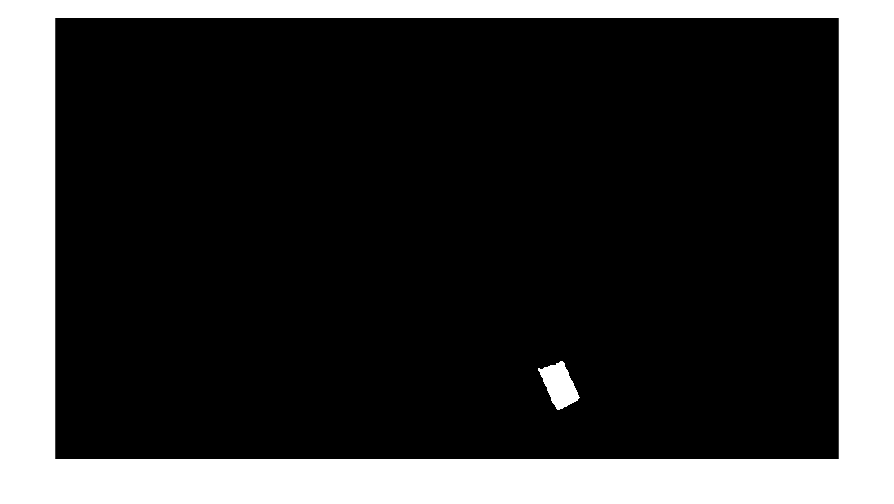

% uses feature extracted from lab and hsv
% b extracts blue color over yellow, v avoids blue areas with low
% brightness, l furtehr caters for some corner case of blue reflection on top of the robot
% arm
bluemask = b < -28 & v > 0.3 & l < 50;
bluemask = imfill(bluemask, "holes");
bluemask = bwareaopen(bluemask, 200);
SE = strel("disk", 3);
% bluemask = imopen(bluemask, SE);
bluemask = imclose(bluemask, SE);
imshow(bluemask)

% imshowpair(bluemask, bluemas, "montage");

Overlaying masks

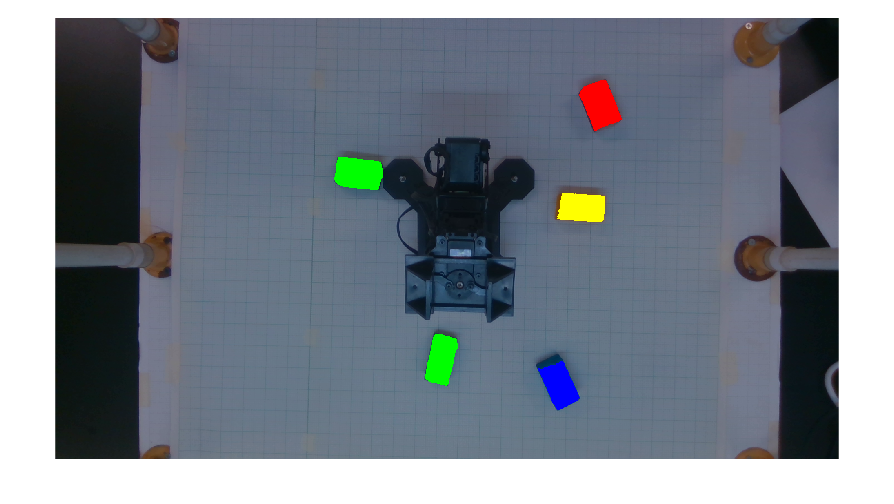

% Viewing the color segmentation
k1 = imoverlay(img1, redmask, "red");
k2 = imoverlay(k1, greenmask, "green");
k3 = imoverlay(k2, bluemask, "blue");
overlayimg = imoverlay(k3, yellowmask, "yellow");
imshow(overlayimg)

(iv) As evident, the masks work with a high success rate and distinguishes all colors in all 9 images in various locations. The masks are flexible enough to recognize colors in slight shadow conditions. In some cases, there are a few spots in between or undetected corners in the image. This is beacuse our masks are not adaptive and depedent on the ambient light. Therefore, a fair amount of change in light conditions can impact the performance of the segmentation masks.

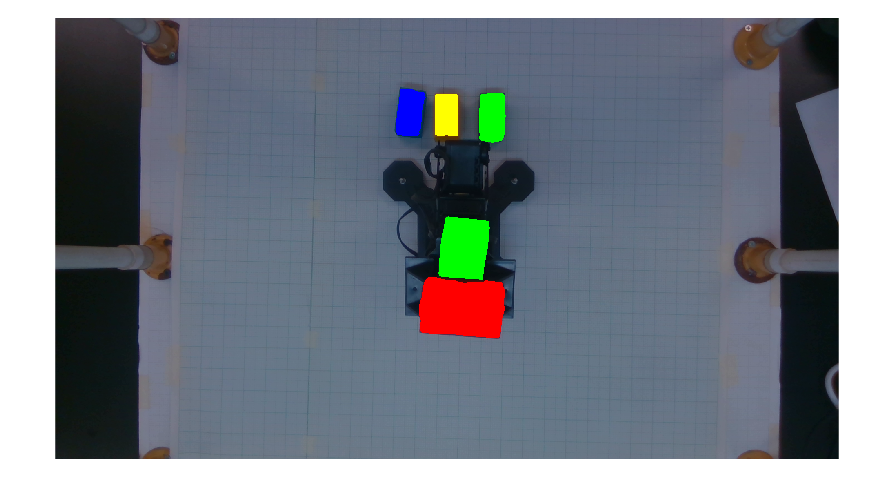


% use function
[label, rgblabel, overlayimg, CC] = segment_objects("intro to rob/7_Color.png", "all");

imshow(overlayimg);

**Task 2.11**

a) Our code for color segmentation was working fine. We however, identified three problems, and correspodingly improved segmentation pipeline to overcome them

- There were some holes in the segmented masks. We filled them using the imfill function. Imfill fills any unmasked area for which a bath from the border to the area does not exist. Since the holes were within an enclosed area, the imfill function filled them

- The edges were rough and left out. We used imclose operation to smoothen out the mask. The close operation performs dilation which increases the masked area by a few pixel. The dilation operation does the opppsite. The net effect is that first a lot of edges pixels are masked and then some of the overrdone pixels are removed.

- There were a few (2- 4) unwanted segmentations in the background of very small sizes (< 100 pixels). We removed them by using the bwareaopen function to exclude the small mask areas. bwareaopen removes the connected components of the masked area which are smaller than the specified size. 

The function takes in 2 arguments

- img_path : the path of the image directory

- color: can be "red", "yellow", "green", "blue" or "all"

function [label, rgblabel, overlayimg, CC] = segment_objects(img_path, color)
    % Reading the image
    img1 = imread(img_path);
    
    % Converting rgb to LAB
    img1lab = rgb2lab(img1);
    [l a b] = imsplit(img1lab);

    % Converting rgb to HSV
    img1hsv = rgb2hsv(img1);
    [h s v] = imsplit(img1hsv);

    % creating empty masks
    sz = size(img1(:,:,1));
    redmask = zeros(sz);
    yellowmask = zeros(sz);
    greenmask = zeros(sz);
    bluemask = zeros(sz);

    if color == "red" | color == "all"
        redmask = h > 0.9 & s > 0.5 ;
        redmask = imfill(redmask, "holes"); % filling holes
        redmask = bwareaopen(redmask, 200); % size of actual box around 8200
        SE = strel("disk", 3); % creating a disk strel
        redmask = imclose(redmask, SE); % perofrming close operation to smoothen edges
        % imshow(redmask);
    end

    if color == "yellow" | color == "all"
        % h extracts color, s extracts regions of yellow with ihgh saturation and v
        % ignores the dark yellow areas of the camera stand
        yellowmask = s > 0.5 & h < 0.105 & v > 0.45;
        yellowmask = imfill(yellowmask, "holes"); % as above
        yellowmask = bwareaopen(yellowmask, 200);
        SE = strel("disk", 3);
        yellowmask = imclose(yellowmask, SE);
    end

    if color == "green" | color == "all"
        greenmask = a < -10;
        greenmask = imfill(greenmask, "holes"); % as above
        greenmask = bwareaopen(greenmask, 200);
        SE = strel("disk", 3);
        greenmask = imclose(greenmask, SE);
    end

    if color == "blue" | color == "all"
        bluemask = b < -28 & v > 0.3 & l < 50;
        bluemask = imfill(bluemask, "holes"); % as above
        bluemask = bwareaopen(bluemask, 200);
        SE = strel("disk", 3);
        bluemask = imclose(bluemask, SE);
    end

    % combining masks

    allcubemask = redmask | greenmask | yellowmask | bluemask;

    % remove the small non-cube noise masked pixels from amsk
    allcubemask = bwpropfilt(allcubemask, "Area", [100 1080*1920]);
    % find connected components
    CC = bwconncomp(allcubemask);

    % finding labels
    label = bwlabel(allcubemask);

    % converting labels to rgb
    rgblabel = label2rgb(label, "jet","k", "shuffle");

    % Viewing the color segmentated image
    k1 = imoverlay(img1, redmask, "red");
    k2 = imoverlay(k1, greenmask, "green");
    k3 = imoverlay(k2, bluemask, "blue");
    overlayimg = imoverlay(k3, yellowmask, "yellow");

    % overlayimg = labeloverlay(img1, label);
    
    
end

